% read video file
vidReader = VideoReader('./video/hw3-video.mp4','CurrentTime',1);
% init opticFlow object
opticFlow = opticalFlowLK('NoiseThreshold',0.009);

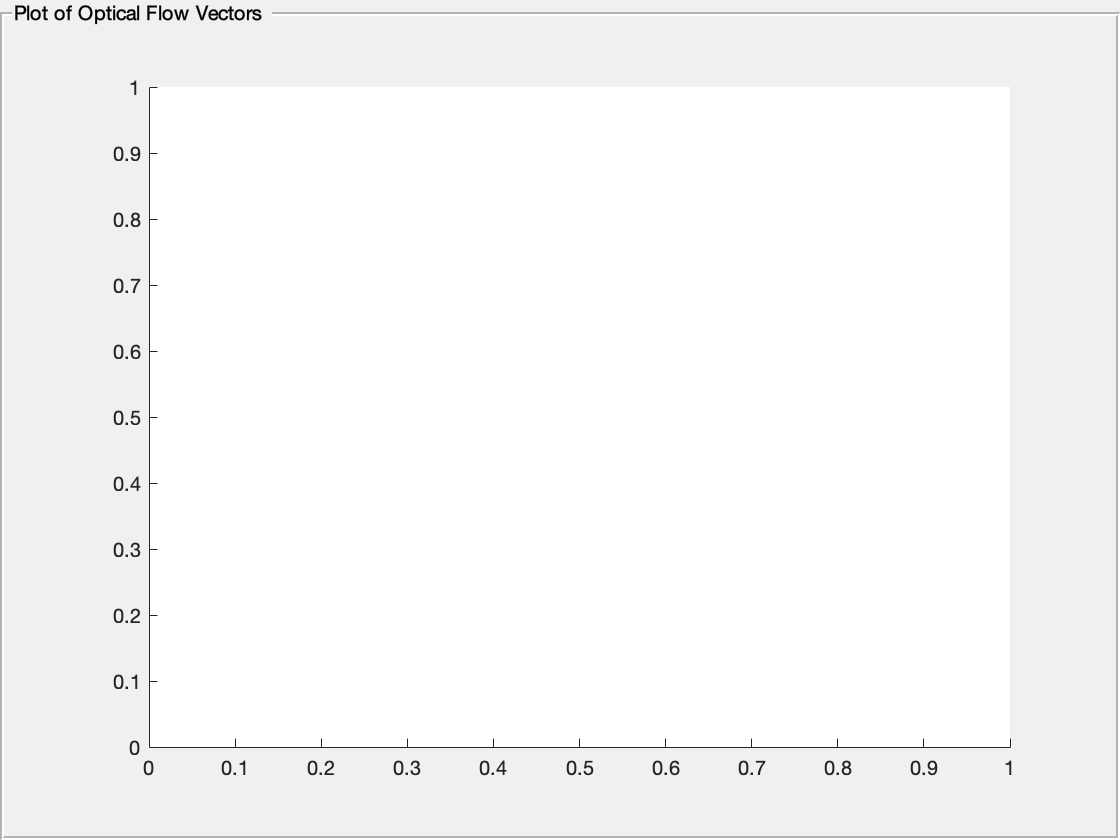

% init plot object
h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

% estimate optical flow
while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = rgb2gray(frameRGB); % in some versions, using im2grpy(frameRGB)
    
    flow = estimateFlow(opticFlow,frameGray);
    
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
    hold off
    pause(10^-3)
end